# Advanced Twistor Theory Demonstration

This script demonstrates advanced features of twistor theory including the Penrose transform, holomorphic bundles, and β-plane integration

clear; close all; clc;

## Initialize Advanced Twistor Field

fprintf('Initializing Advanced Twistor Field\n');

Initializing Advanced Twistor Field


fprintf('===================================\n\n');


% Create an advanced twistor field object
adv_field = mlraut.TwistorAdvanced('gauge_group', 'U1', ...
                           'n_points', 25, ...
                           'x_range', [-2, 2], ...
                           'slice_type', 'euclidean');

## Example 1: Complete Ward Construction with Advanced Features

fprintf('Example 1: Complete Ward Construction\n');

Example 1: Complete Ward Construction


fprintf('------------------------------------\n\n');

------------------------------------




Advanced Twistor Theory Demonstration

1. Constructing holomorphic vector bundle over PT...
Constructing holomorphic vector bundle...
Holomorphic bundle constructed.

2. Performing Penrose transform...
Performing Penrose transform...
Penrose transform completed.

3. Demonstrating β-plane integration...
   Generated 20 β-planes through origin

4. Creating visualizations...


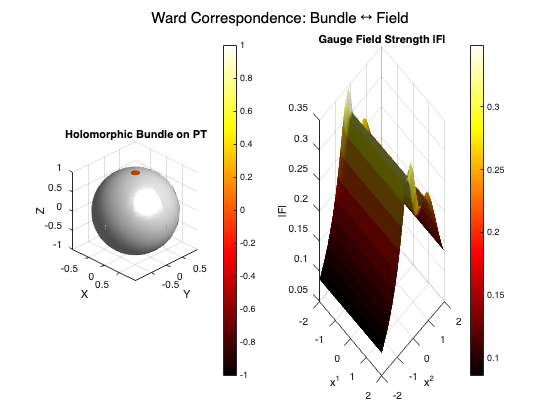

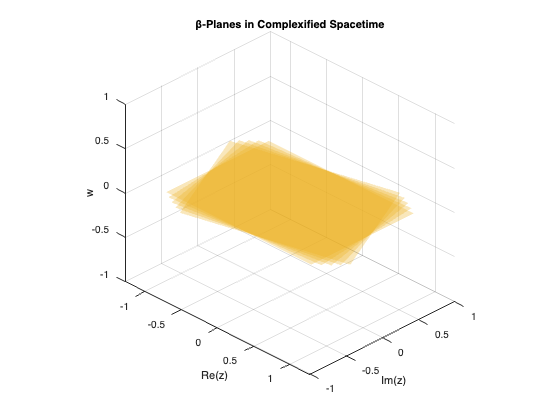


Advanced demonstration complete!



% Run the advanced demonstration
adv_field.demonstrateAdvancedFeatures();

## Example 2: Verify Physical Properties

fprintf('\n\nExample 2: Physical Properties Verification\n');



Example 2: Physical Properties Verification


fprintf('-------------------------------------------\n\n');

-------------------------------------------




% Check Maxwell equations
adv_field.compareWithMaxwellEquations();


Verifying Maxwell Equations
---------------------------
At center point:
  ∇·E = -4.163336e-16 (should be ≈ 0 for vacuum)
  ∇·B = -4.718448e-16 (should be ≈ 0 always)

Self-duality check (F = i*F in Euclidean):
  |E_x - iB_z| = 2.593764e-01


## Example 3: Instanton-like Solution

fprintf('\n\nExample 3: Instanton-like Solution\n');



Example 3: Instanton-like Solution


fprintf('----------------------------------\n\n');

----------------------------------



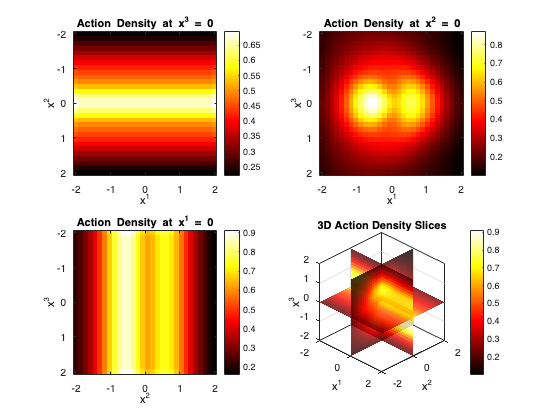


% Create a new field with instanton-like twistor function
instanton_field = mlraut.TwistorAdvanced('gauge_group', 'U1', ...
                                 'n_points', 30, ...
                                 'slice_type', 'euclidean');

% Define BPST instanton-like twistor function inline
instanton_field.twistor_function = @(W) exp(1i * 1.0^2 / (abs(W(1))^2 + abs(W(2))^2 + 1.0^2));

% Compute fields
instanton_field.computeGaugeFields();

% Visualize the instanton profile
figure('Name', 'Instanton Profile');

% Action density ~ F^2
F_squared = instanton_field.field_strength.Ex.^2 + ...
           instanton_field.field_strength.Ey.^2 + ...
           instanton_field.field_strength.Ez.^2 + ...
           instanton_field.field_strength.Bx.^2 + ...
           instanton_field.field_strength.By.^2 + ...
           instanton_field.field_strength.Bz.^2;

% Take slices through the origin
mid = floor(instanton_field.n_points / 2);

subplot(2, 2, 1);
imagesc(instanton_field.x_range, instanton_field.x_range, ...
        squeeze(sqrt(F_squared(:, :, mid))));
colormap(hot); colorbar;
xlabel('x^1'); ylabel('x^2');
title('Action Density at x^3 = 0');
axis equal tight;

subplot(2, 2, 2);
imagesc(instanton_field.x_range, instanton_field.x_range, ...
        squeeze(sqrt(F_squared(:, mid, :))));
colormap(hot); colorbar;
xlabel('x^1'); ylabel('x^3');
title('Action Density at x^2 = 0');
axis equal tight;

subplot(2, 2, 3);
imagesc(instanton_field.x_range, instanton_field.x_range, ...
        squeeze(sqrt(F_squared(mid, :, :))));
colormap(hot); colorbar;
xlabel('x^2'); ylabel('x^3');
title('Action Density at x^1 = 0');
axis equal tight;

subplot(2, 2, 4);
% 3D visualization using slices instead of isosurface
[X, Y, Z] = meshgrid(linspace(instanton_field.x_range(1), instanton_field.x_range(2), instanton_field.n_points));
F_sqrt = sqrt(F_squared);

% Show orthogonal slices
h = slice(X, Y, Z, F_sqrt, 0, 0, 0);
set(h, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
colormap(hot);
colorbar;

xlabel('x^1'); ylabel('x^2'); zlabel('x^3');
title('3D Action Density Slices');
axis equal; grid on;
view(45, 30);
box on;

## Example 4: Penrose Transform Visualization

fprintf('\n\nExample 4: Penrose Transform Details\n');



Example 4: Penrose Transform Details


fprintf('------------------------------------\n\n');

------------------------------------




% Perform detailed Penrose transform
adv_field.performPenroseTransform();

Performing Penrose transform...
Penrose transform completed.


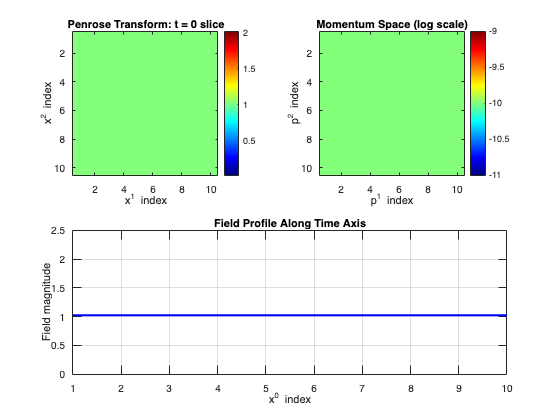


% Visualize the transform
if ~isempty(adv_field.penrose_transform)
    figure('Name', 'Penrose Transform');
    
    % Get the transformed field
    transformed = adv_field.penrose_transform.field;
    grid_data = adv_field.penrose_transform.grid;
    
    % Show slices of the 4D transformed field
    subplot(2, 2, 1);
    slice_idx = floor(size(transformed, 1) / 2);
    imagesc(squeeze(abs(transformed(slice_idx, :, :, 5))));
    colormap(jet); colorbar;
    title('Penrose Transform: t = 0 slice');
    xlabel('x^1 index'); ylabel('x^2 index');
    
    subplot(2, 2, 2);
    % Show Fourier transform to see momentum space
    ft_field = fftn(transformed);
    ft_slice = squeeze(abs(ft_field(slice_idx, :, :, 5)));
    imagesc(fftshift(log10(ft_slice + 1e-10)));
    colormap(jet); colorbar;
    title('Momentum Space (log scale)');
    xlabel('p^1 index'); ylabel('p^2 index');
    
    subplot(2, 2, [3, 4]);
    % Profile along a line
    profile = squeeze(abs(transformed(:, 5, 5, 5)));
    plot(1:length(profile), profile, 'b-', 'LineWidth', 2);
    xlabel('x^0 index'); ylabel('Field magnitude');
    title('Field Profile Along Time Axis');
    grid on;
end

## Example 5: Twistor Space Fibration

fprintf('\n\nExample 5: Twistor Space Fibration\n');



Example 5: Twistor Space Fibration


fprintf('-----------------------------------\n\n');

-----------------------------------



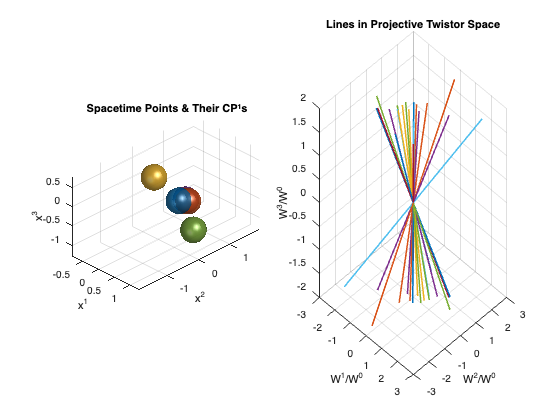


figure('Name', 'Twistor Space Fibration');

% Visualize the fibration PT → S⁴
% Each point in spacetime corresponds to a CP¹ in twistor space

% Sample spacetime points
n_samples = 5;
spacetime_points = 2 * rand(n_samples, 4) - 1;

colors = lines(n_samples);

subplot(1, 2, 1);
hold on;

% For each spacetime point, show its corresponding CP¹
for i = 1:n_samples
    x_point = spacetime_points(i, :);
    
    % Generate the corresponding CP¹
    theta = linspace(0, pi, 30);
    phi = linspace(0, 2*pi, 30);
    [Theta, Phi] = meshgrid(theta, phi);
    
    % Embed in R³ for visualization
    scale = 0.3;
    X = scale * sin(Theta) .* cos(Phi) + x_point(1);
    Y = scale * sin(Theta) .* sin(Phi) + x_point(2);
    Z = scale * cos(Theta) + x_point(3);
    
    surf(X, Y, Z, 'FaceColor', colors(i, :), 'EdgeColor', 'none', ...
         'FaceAlpha', 0.7);
end

xlabel('x^1'); ylabel('x^2'); zlabel('x^3');
title('Spacetime Points & Their CP¹s');
axis equal; grid on;
view(45, 30);
lighting gouraud; light;

subplot(1, 2, 2);
% Show the dual picture: lines in PT
hold on;

% Each line in PT corresponds to a point in spacetime
for i = 1:20
    % Random line in projective space
    t = linspace(-2, 2, 50);
    
    % Parametric line
    x_line = 0.5 * randn() * t;
    y_line = 0.5 * randn() * t;
    z_line = t;
    
    plot3(x_line, y_line, z_line, 'LineWidth', 1.5);
end

xlabel('W^1/W^0'); ylabel('W^2/W^0'); zlabel('W^3/W^0');
title('Lines in Projective Twistor Space');
grid on;
view(45, 30);

## Summary and Conclusions

fprintf('\n\nSummary of Advanced Features\n');



Summary of Advanced Features


fprintf('============================\n');

fprintf('1. Ward Correspondence: Complex vector bundles ↔ Self-dual gauge fields\n');

1. Ward Correspondence: Complex vector bundles ↔ Self-dual gauge fields


fprintf('2. Penrose Transform: Cohomology on PT → Fields on spacetime\n');

2. Penrose Transform: Cohomology on PT → Fields on spacetime


fprintf('3. β-plane Integration: Key to extracting gauge fields from twistor data\n');

3. β-plane Integration: Key to extracting gauge fields from twistor data


fprintf('4. Holomorphic Bundles: Encode all information about self-dual fields\n');

4. Holomorphic Bundles: Encode all information about self-dual fields


fprintf('5. Physical Verification: Fields satisfy Maxwell equations\n');

5. Physical Verification: Fields satisfy Maxwell equations


fprintf('\nThe twistor approach provides a powerful geometric framework\n');


The twistor approach provides a powerful geometric framework


fprintf('for understanding gauge theories and their solutions.\n');

for understanding gauge theories and their solutions.
